# Chapter 6: Batch it up, batch it in, let me begin

Let's go back to GitHub and check in on our new build.

You can now see our new GitHub Actions job running:

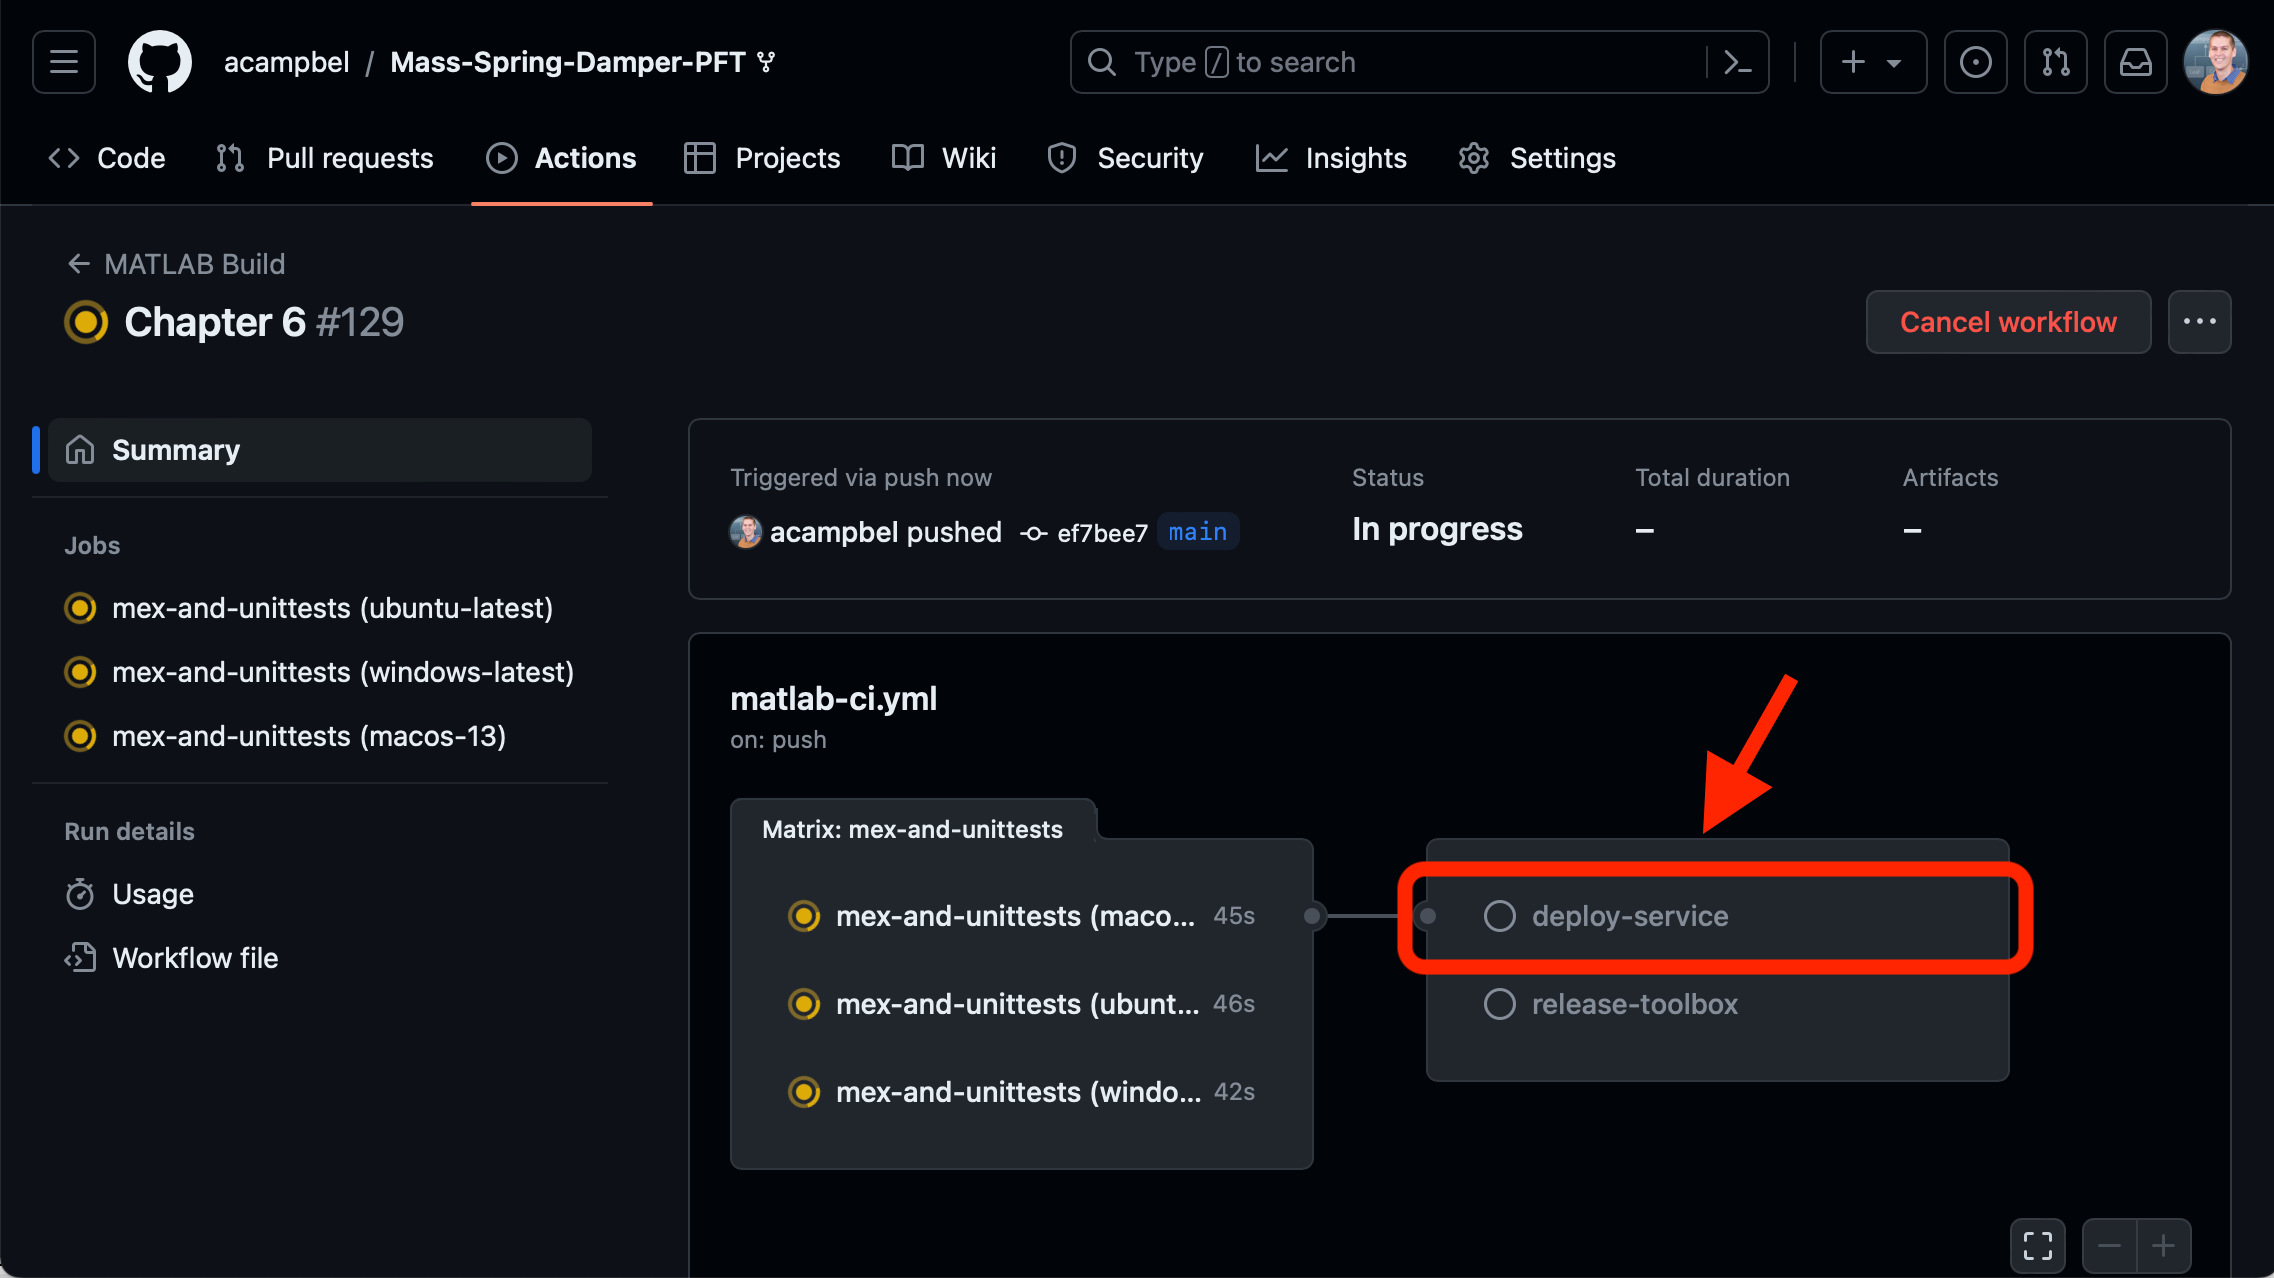

However, in a few minutes we see one more problem:

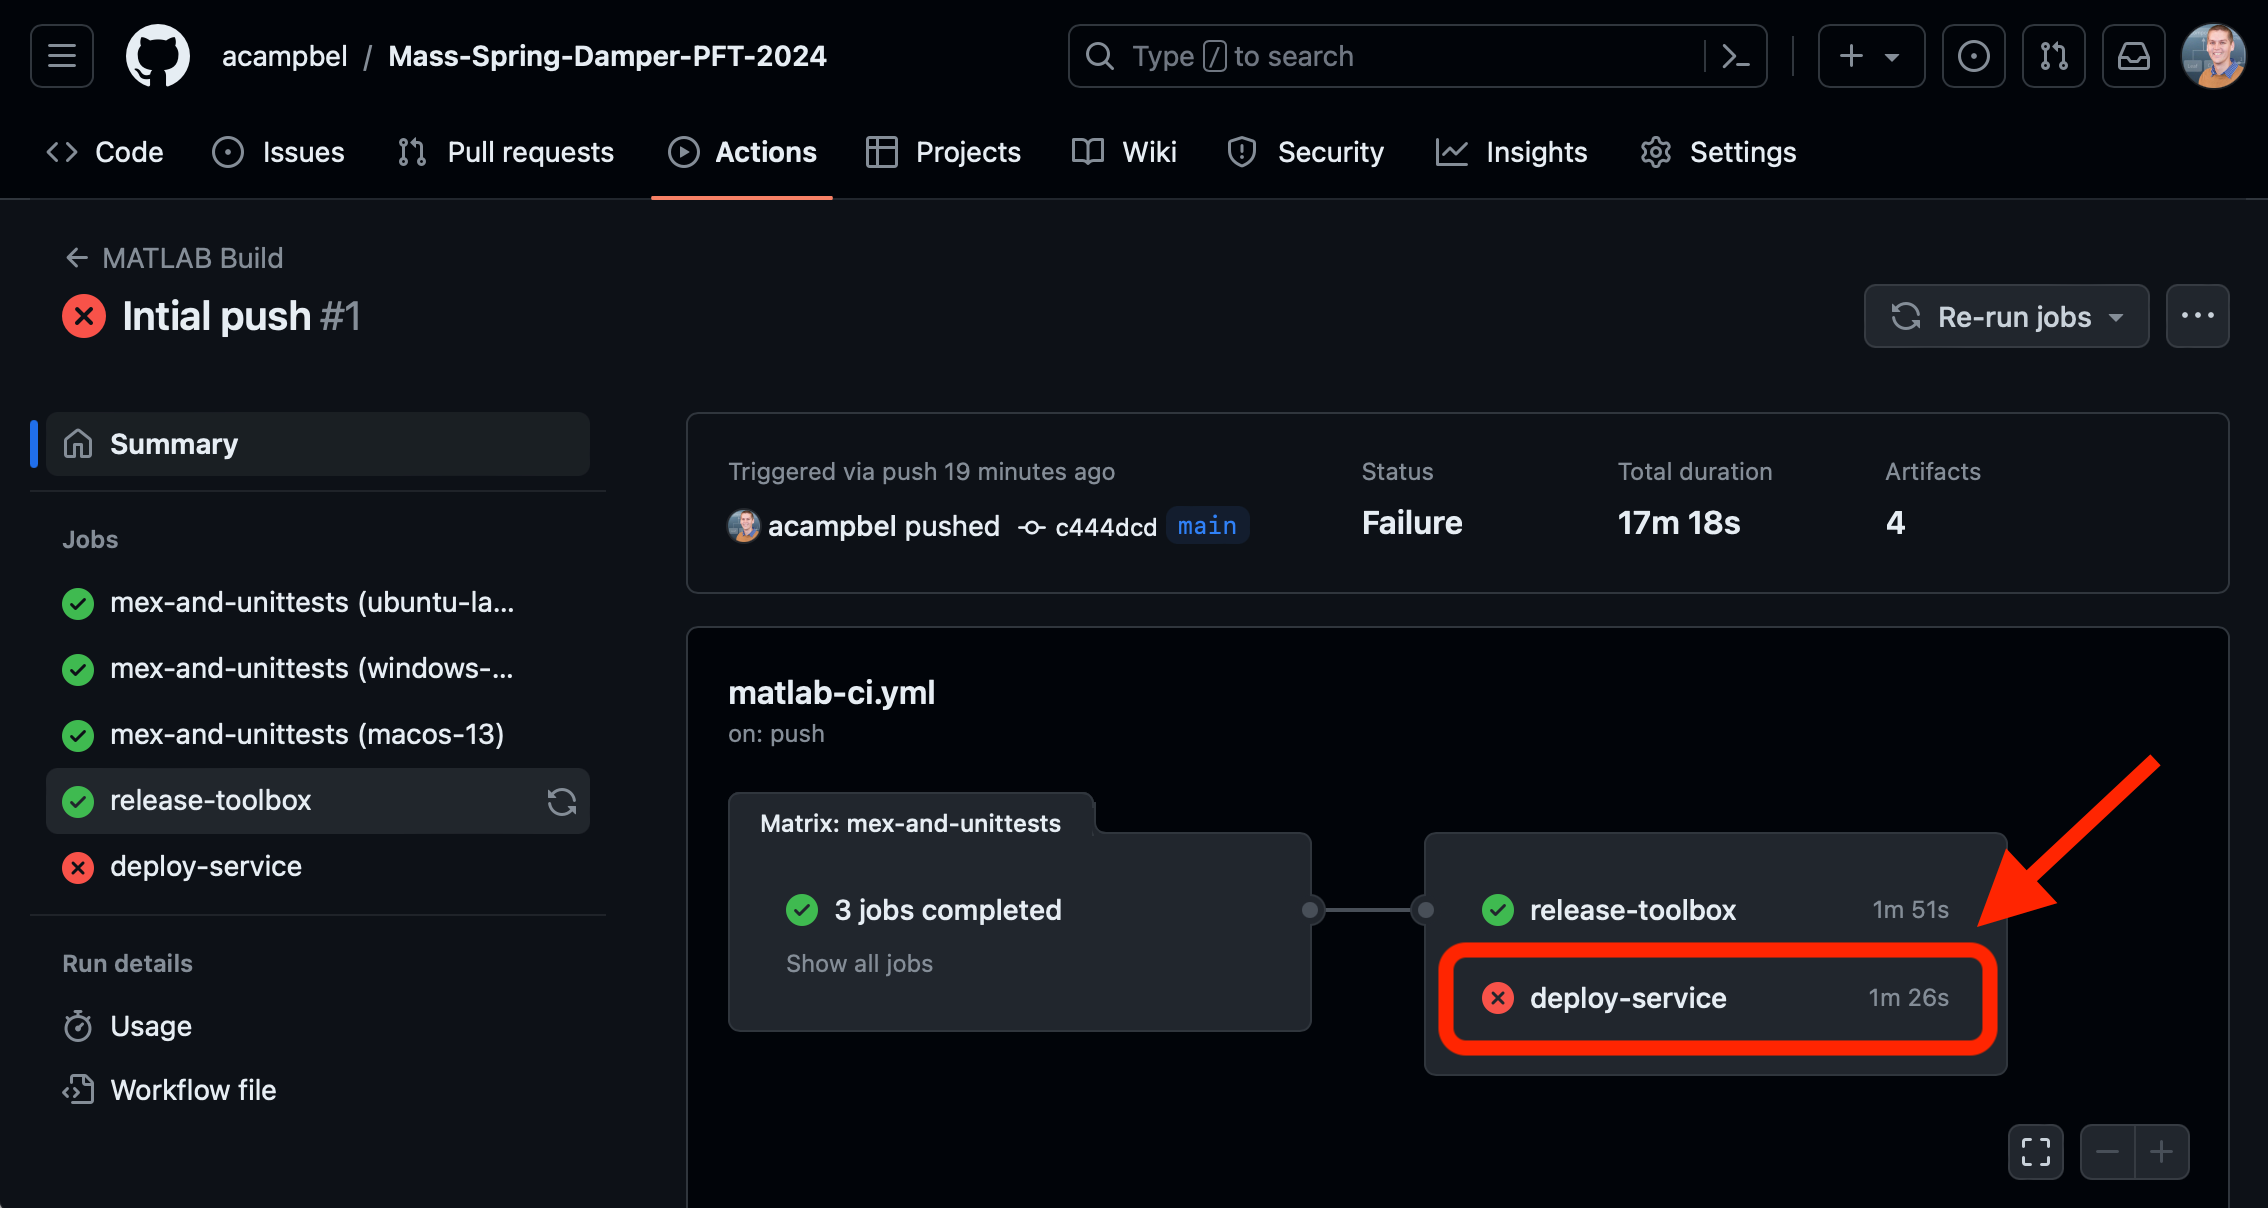

Click through and see what is going on:

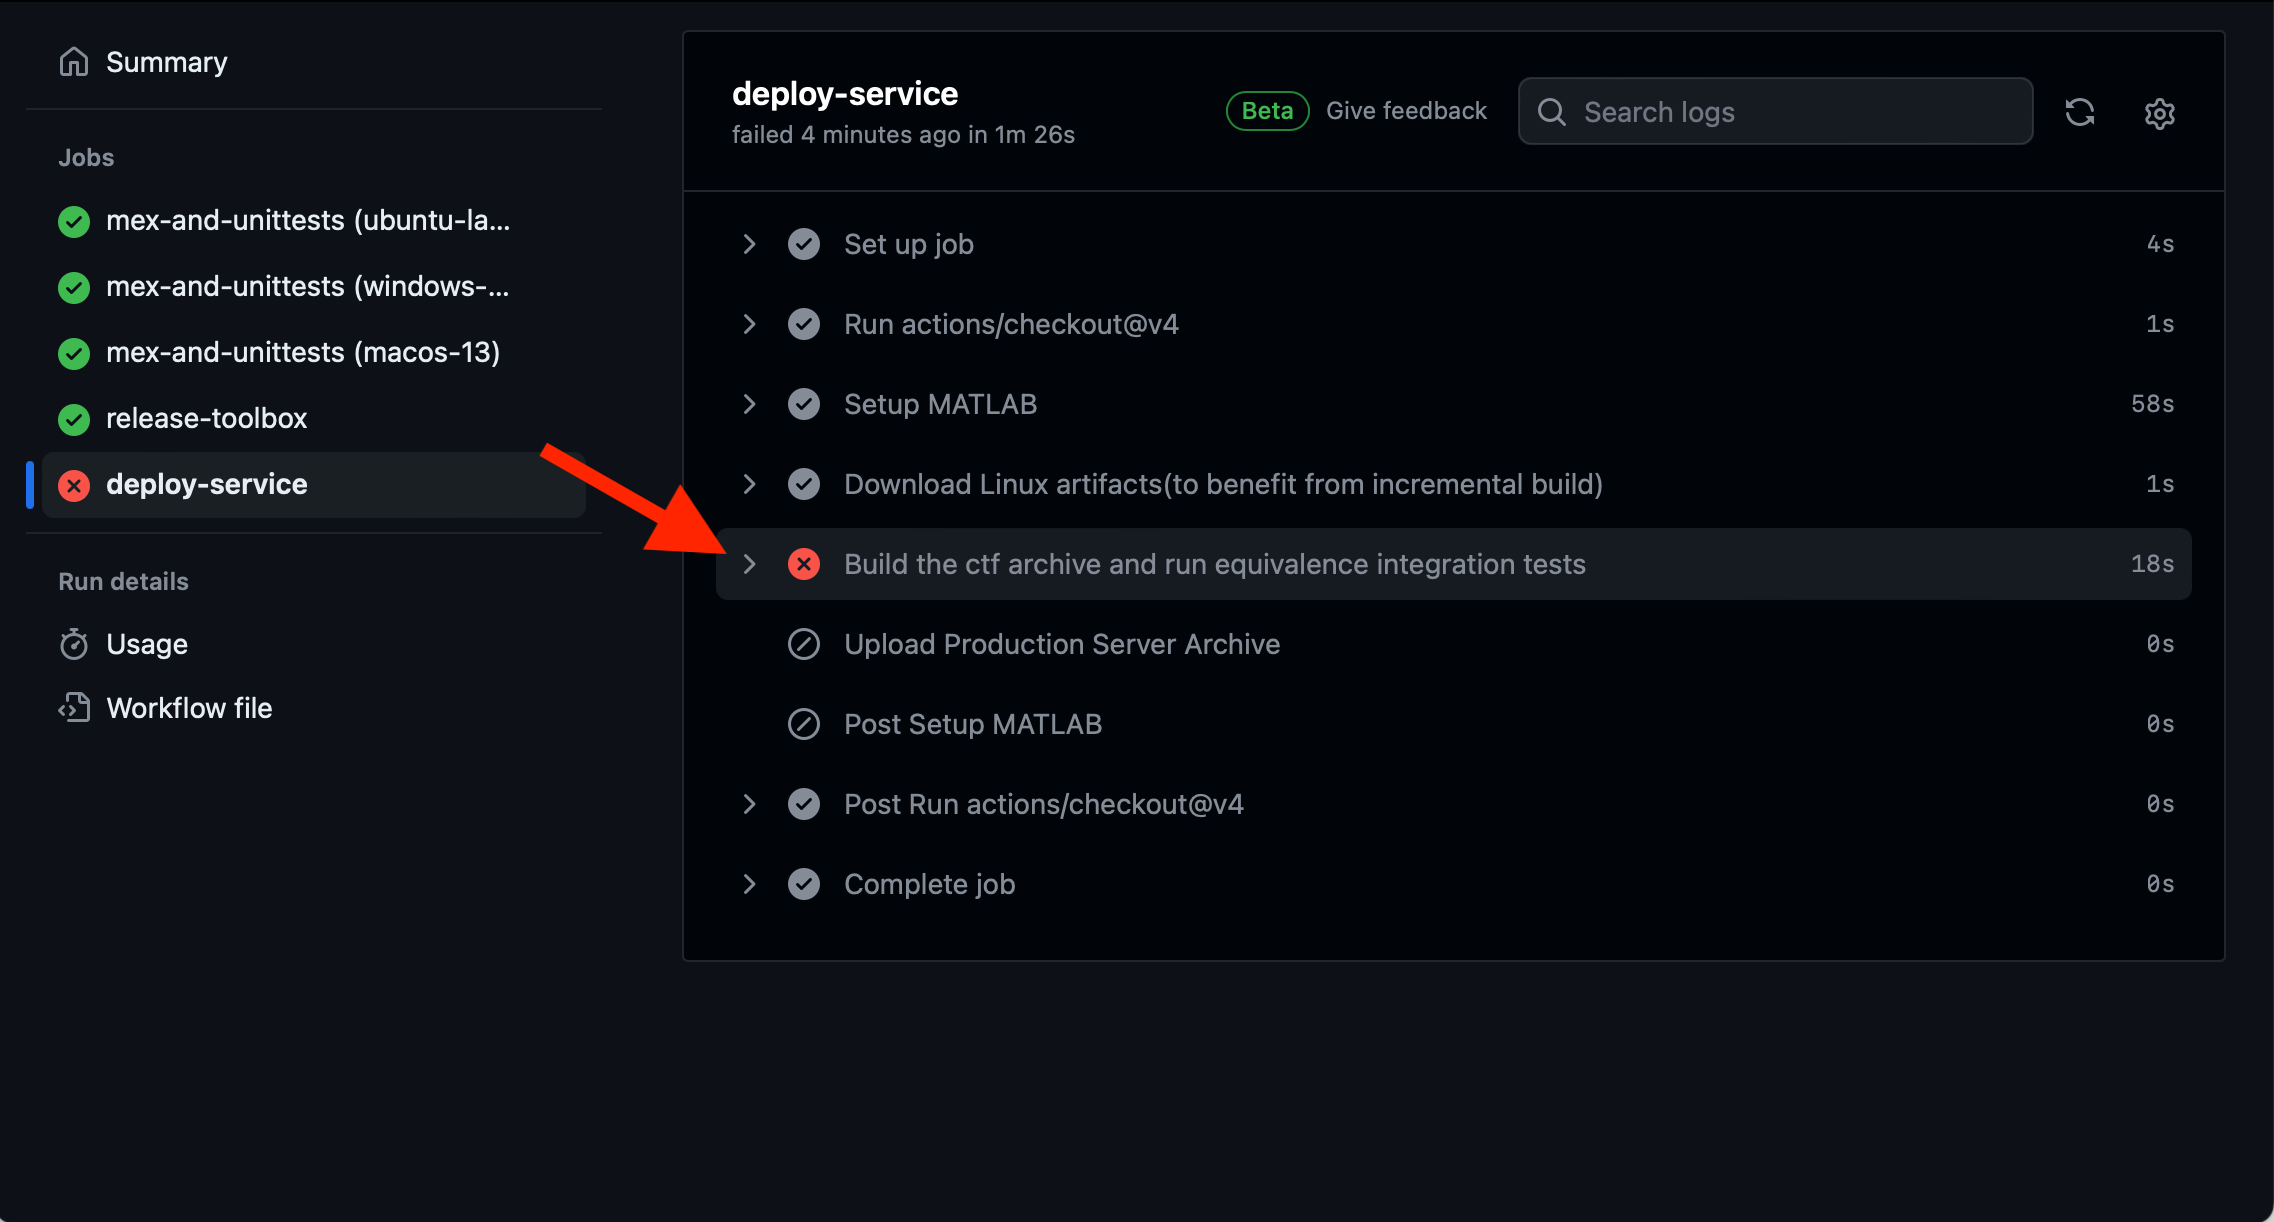

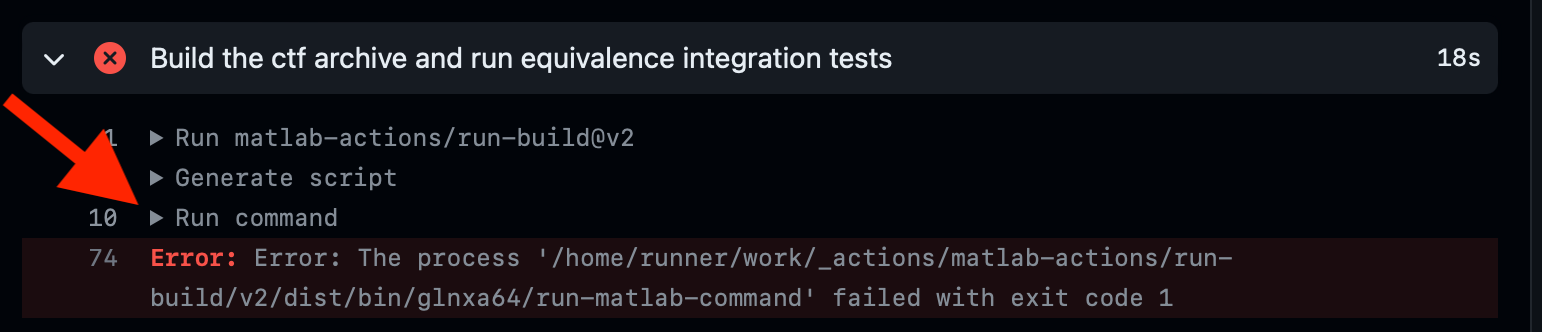

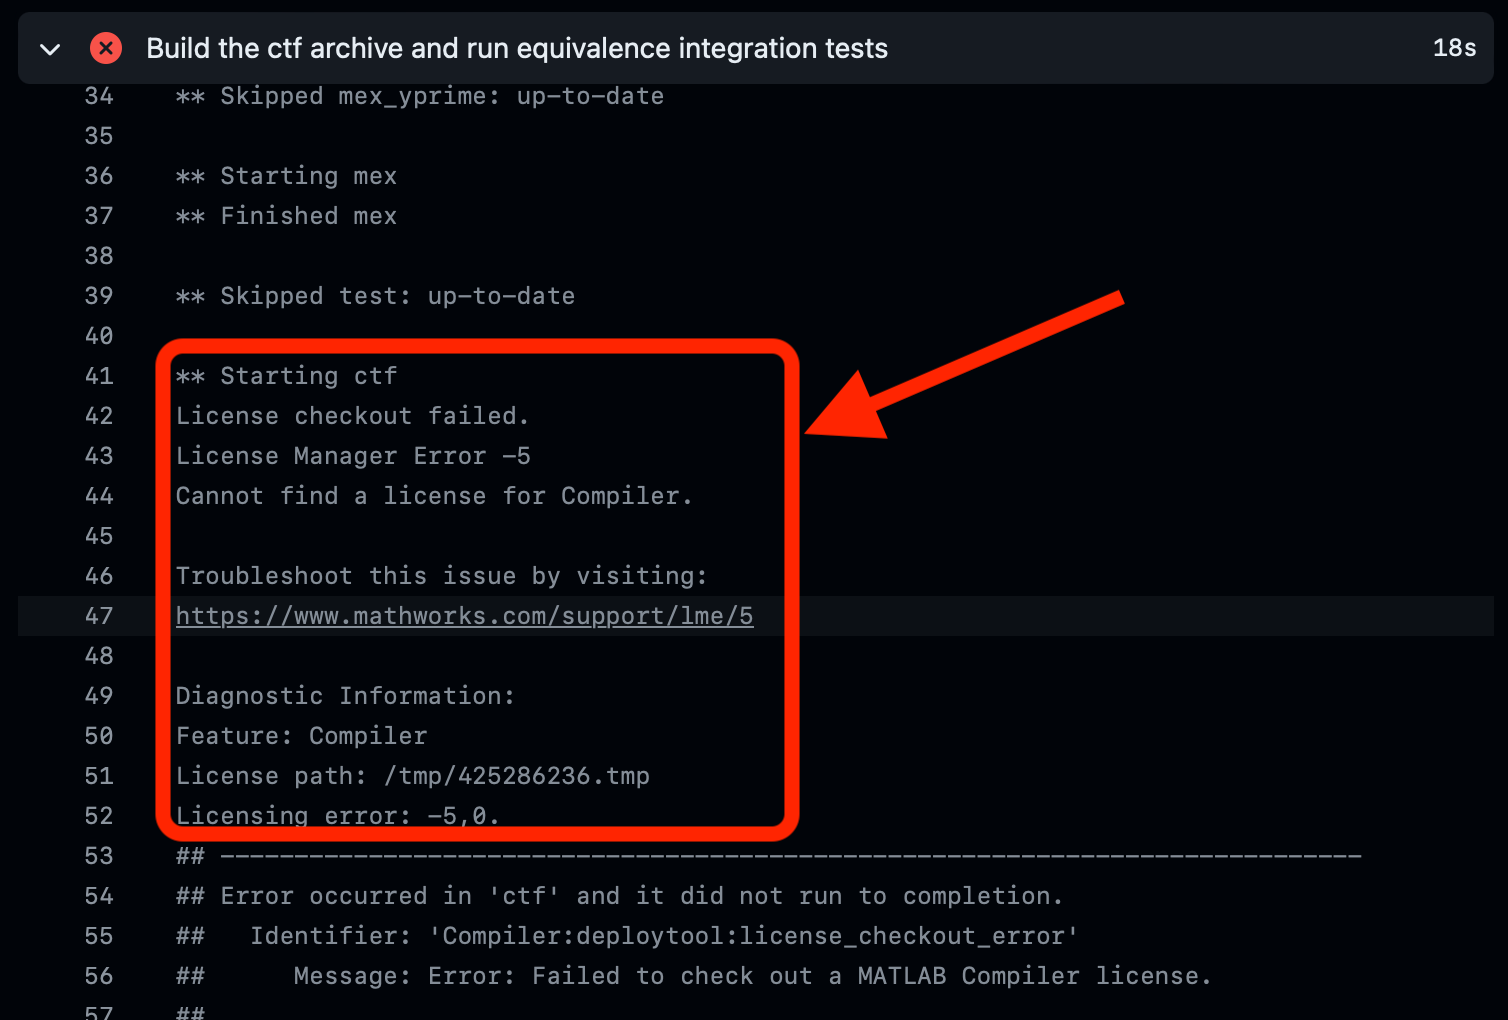

We can't use Compiler! This is because transformation products are not supported by our free licensing for open source projects. These workflows also would fail if the repository was private, which is of course would be the case for many of our customers who want to keep their IP secure.

This is where batch tokens come in.

We have given you a batch token with the appropriate product licenses. Let's go ahead and apply this batch token so our build will succeed.

To do this, navigate to your repository settings.

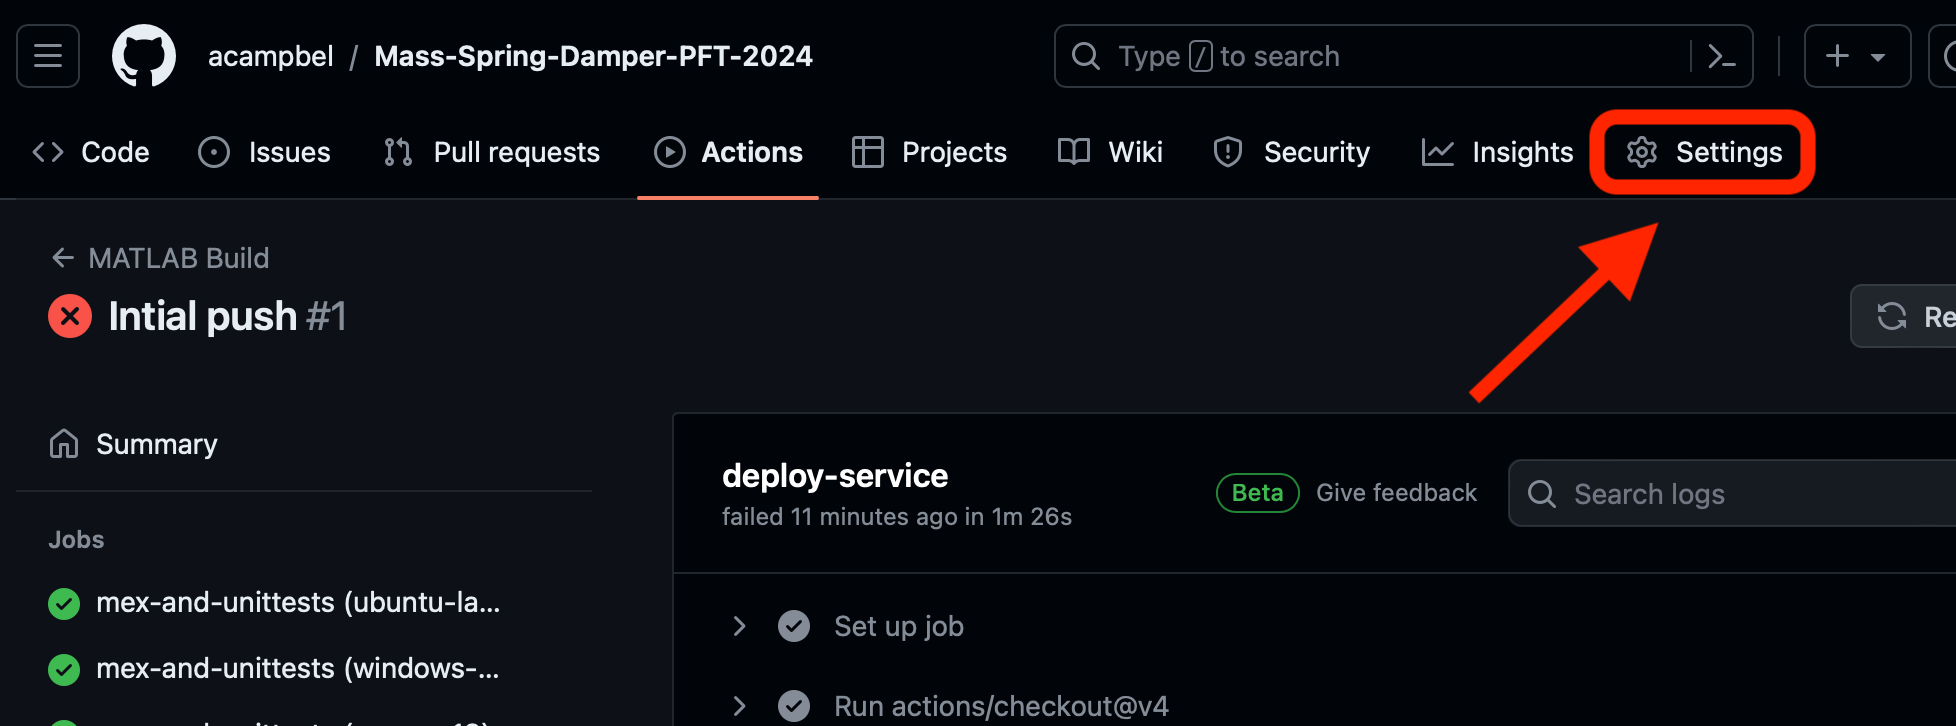

Navigate to *Secrets and variables*

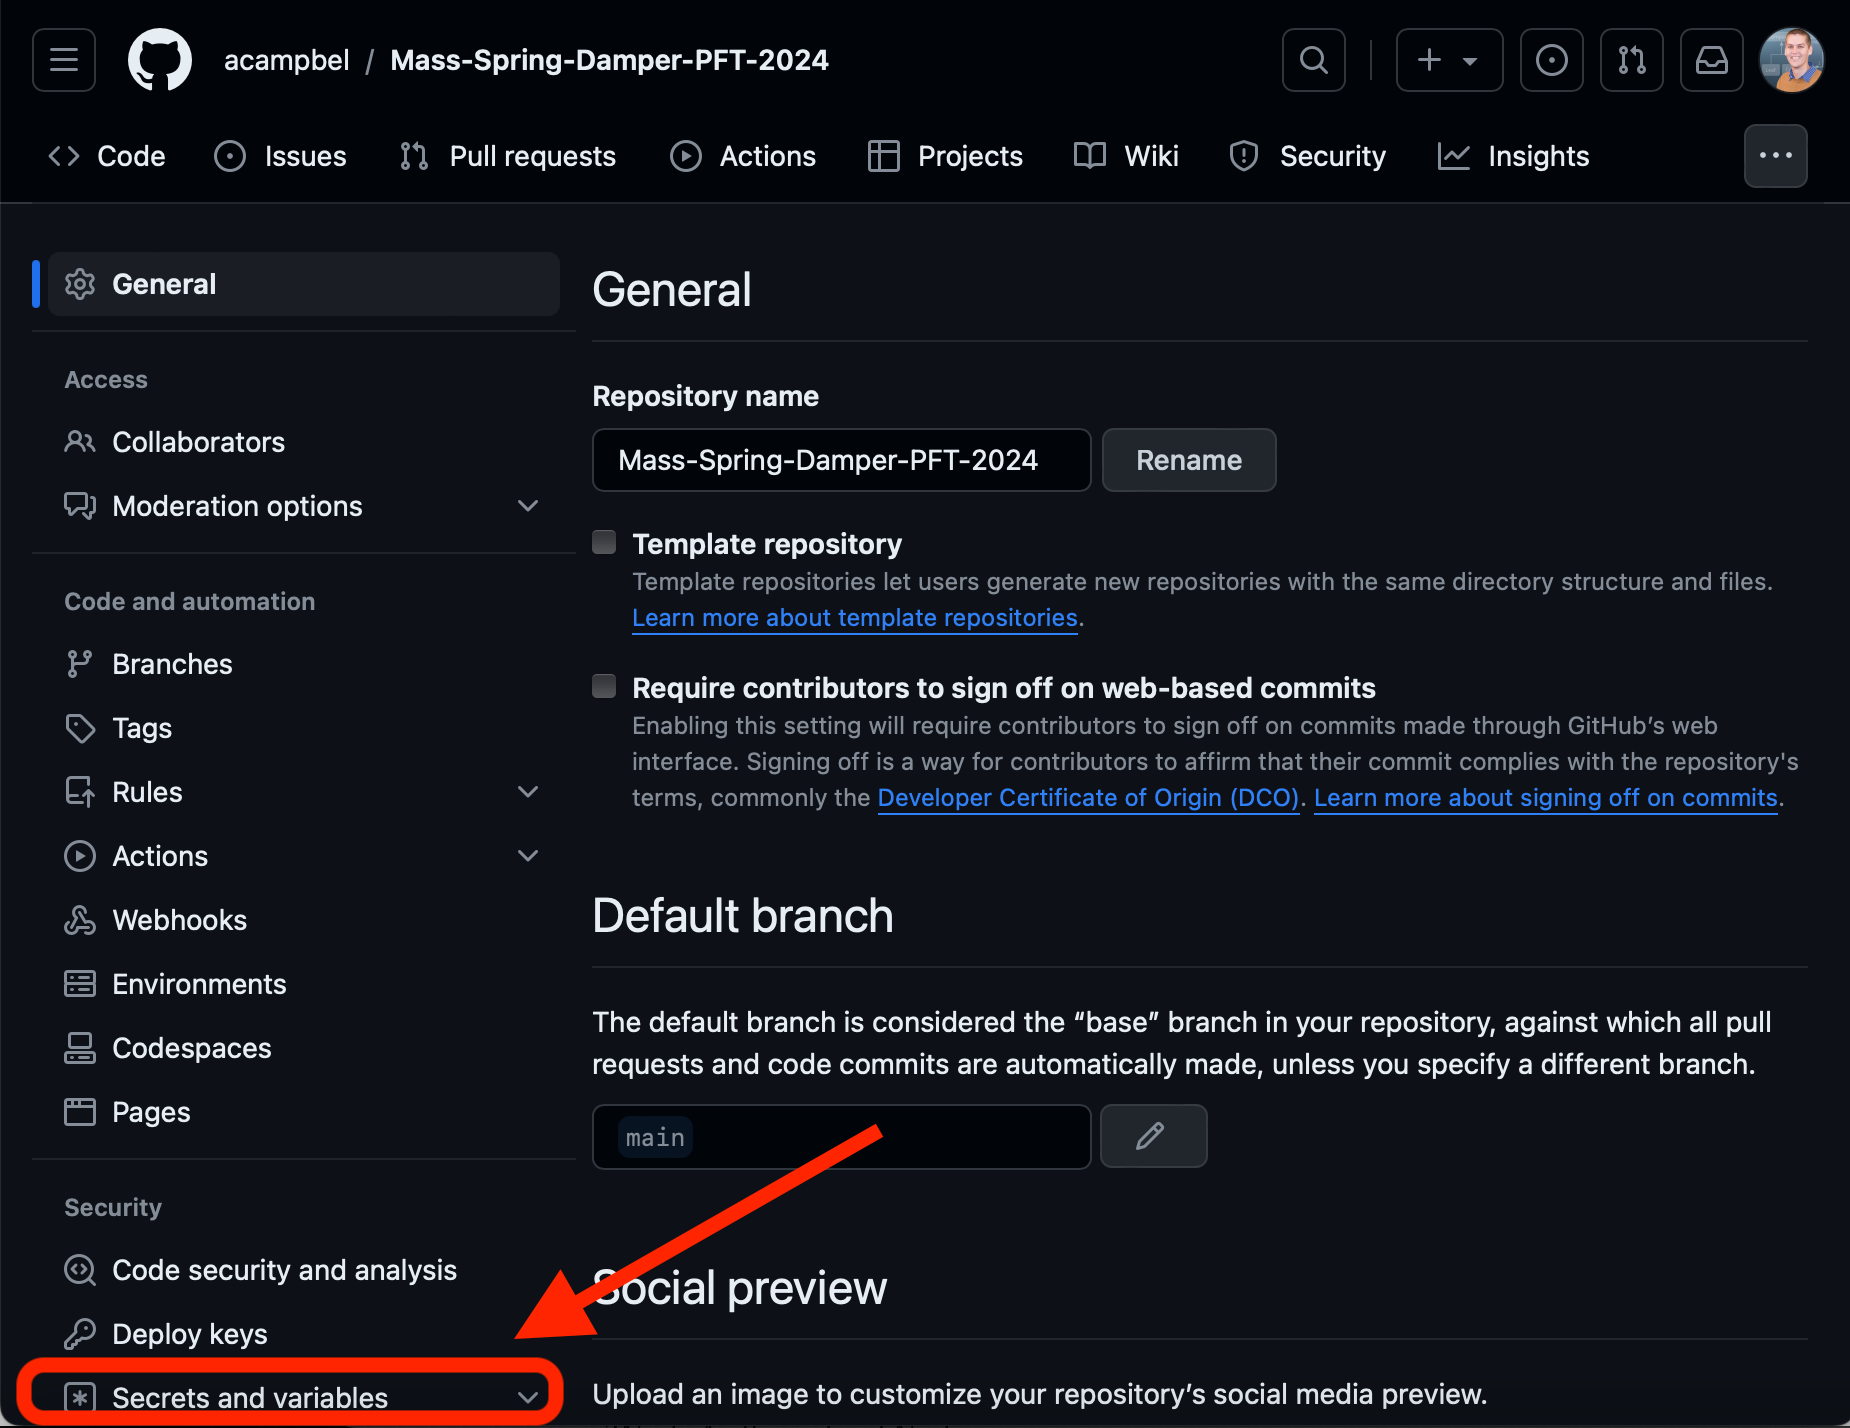

Click "*Actions"*

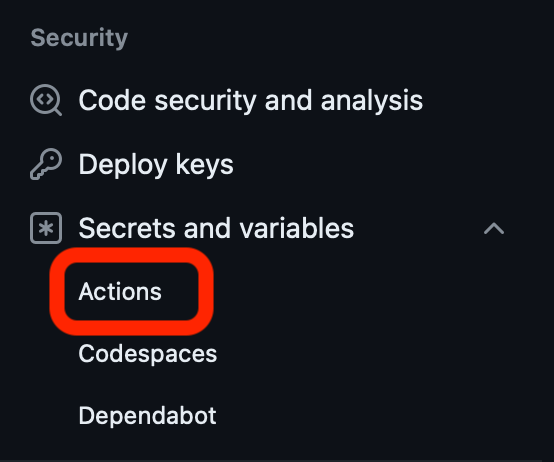

Now click the "*New repository secret*" button

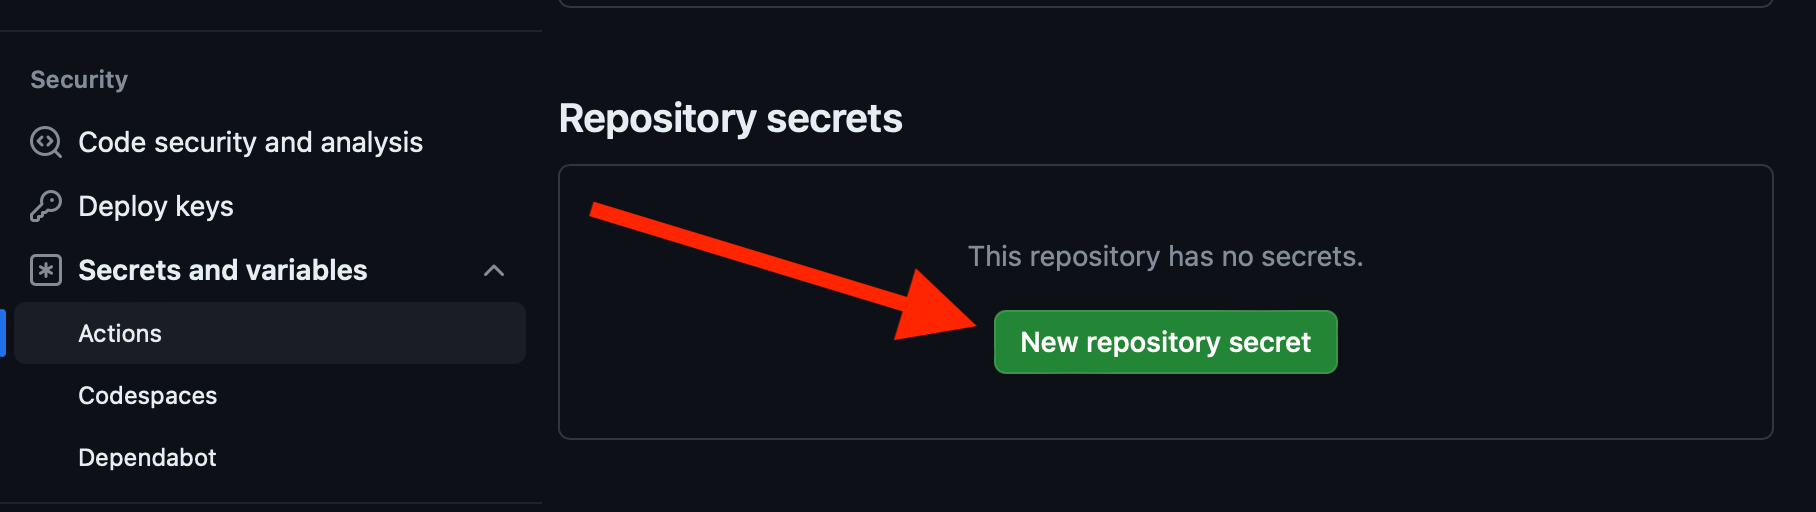

This brings up a page that enables you to give a name and a value to the secret. Name the token:

`MLM_LICENSE_TOKEN`

...paste in the token we have given you in the chat and click "*Add secret*"

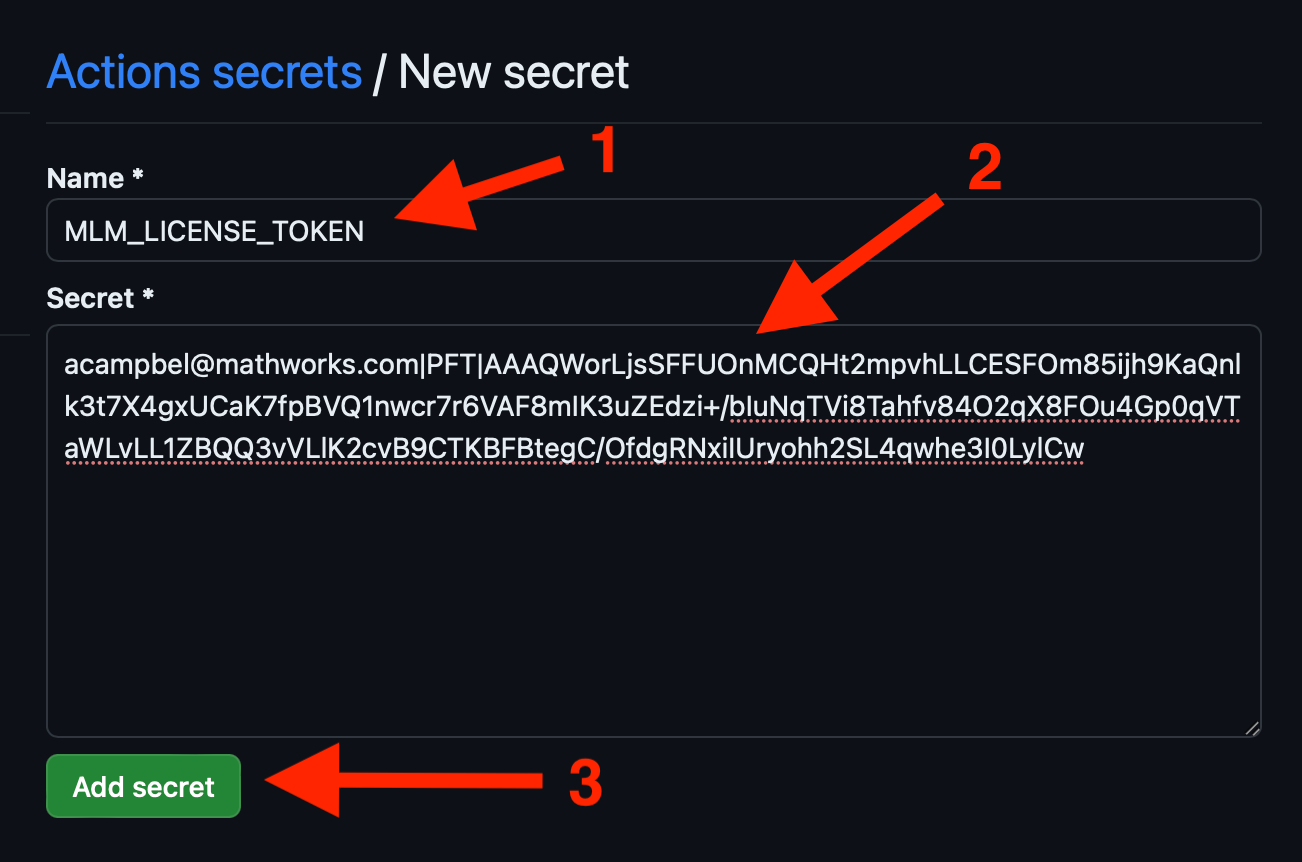

Now your GitHub config has this secret defined, but you still need to expose it to your CI workflow. In MATLAB, go back to the `matlab-ci.yml `file and find the `env` section which defines the workflow environment (Hint: line 14). You can uncomment the code needed to grab the token defined in GitHub secrets, and put that into the environment that runs the build.

openFile .github/workflows/matlab-ci.yml
showCode .github/workflows/matlab-ci.yml 12:14

12    env:
13      PRODUCT_LIST: MATLAB MATLAB_Test MATLAB_Compiler MATLAB_Compiler_SDK
14      MLM_LICENSE_TOKEN: ${{secrets.MLM_LICENSE_TOKEN}}


Now commit and push! After a few minutes you see this automatically create what you need to deploy to production.

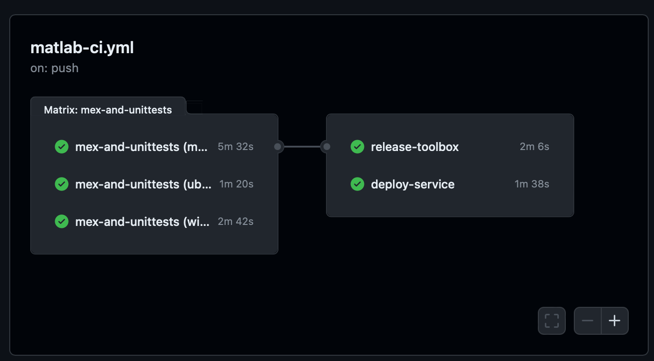

Congratulations. Today you have learned quite a few things:

- How to leverage the build tool for consistent reproducibility

- The benefits of incremental builds

- How to implement new tasks in a buildfile, using both task functions in your buildfile and pre-made tasks like the TestTask

- How to write an equivalence test to confirm that a compiled and deployed artifact produces the same result as the MATLAB algorithm

- That you can manage quality of your toolbox through the Quality Dashboard and its associated tools and reports

- The benefits of leveraging consistent CI/CD automation, and that a hosted platform like GitHub Actions can easily manage all the workers/runners needed to run through your automation

- How to apply batch tokens in a CI/CD platform like GitHub Actions

Now go and leverage these tools for all your projects and lead the ways for our customers as well.

#### [Preface & TOC](matlab:open('index.html'))